# Punto 2

Vamos primero a cargar la imagen.

B1 = imread('balcones256.bmp'); % Guardando Imagen en la matriz B1
media = mean(B1(:));

Lo modificamos para que nos de una mejor imagen, creamos el algoritmo

B1_binary = B1 > media; %Transforma en 1 si es mayor que la media, y 0 si es menor que la media
B1_binary

B1_binary = 294×720 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1  

Mostramos la imagen

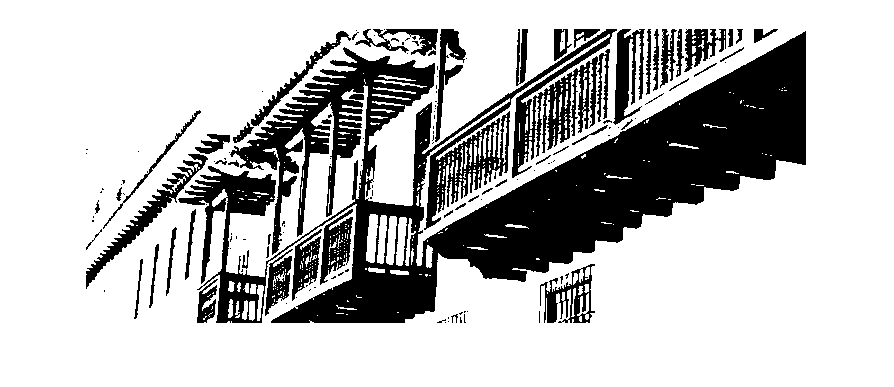

imshow(B1_binary)

Guardamos la imagen

imwrite(B1_binary,'balconesBN_MiguelGutierrez_JulianRamirez.bmp')

# Funciones

Creamos un codigo que convierte de [0,127.5] a 0 y(127.5,255] a 1, si se aplica esta funcion tambien debería funcionar.

function numero = conversion(numero,media)
    if numero <= media
        numero = 0;
    elseif numero > media
        numero = 1;
    end
end